# Final Project: PCA + SVM Portion

**Author:** Rex Rayburg

**Student ID:** 4336366

**D Value:** 66

This live-script will walk through the processing involved with performing PCA on an image classification dataset.

clear
clc
close all

## Part 1 - Data Processing

The dataset contains images of standard playing cards organized into labeled folders corresponding to each card type. Key characteristics of the dataset include:

- 7,624 training images

- 265 validation images

- 265 testing images

- 53 total classes representing each unique playing card (including jokers)

- Images are 224 x 224 RGB color images

### Part A - Loading the Data

For now, I will be utilizing the random split that was already performed when the data was released to the public on Kaggle. This part will load the data into the workspace using datastores and then display a set of the training images for visualization.

% D value
D = 14

D = 14


% Define dataset path
dataPath = fullfile(pwd, 'input');

trainPath = fullfile(dataPath, 'train');
validPath = fullfile(dataPath, 'valid');
testPath  = fullfile(dataPath, 'test');

% Create imageDatastores
imdsAll = imageDatastore({trainPath, validPath, testPath}, ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');

imdsTrain = imageDatastore(trainPath, ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');

imdsValid = imageDatastore(validPath, ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');

imdsTest = imageDatastore(testPath, ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');

% Basic dataset info
disp("Number of training images: " + numel(imdsTrain.Files));

Number of training images: 7624


disp("Number of classes: " + numel(categories(imdsTrain.Labels)));

Number of classes: 53



% Set random seed 
rng(D);

%----

% Custom split ratios
trainRatio = 0.7;
validRatio = 0.15;
testRatio  = 0.15;

% First split: train vs (valid+test)
[imdsTrain, imdsTemp] = splitEachLabel(imdsAll, trainRatio, 'randomized');

% Second split: valid vs test
validPortion = validRatio / (validRatio + testRatio);

[imdsValid, imdsTest] = splitEachLabel(imdsTemp, validPortion, 'randomized');

% Display counts
disp("Training images: " + numel(imdsTrain.Files));

Training images: 5710


disp("Validation images: " + numel(imdsValid.Files));

Validation images: 1236


disp("Test images: " + numel(imdsTest.Files));

Test images: 1208


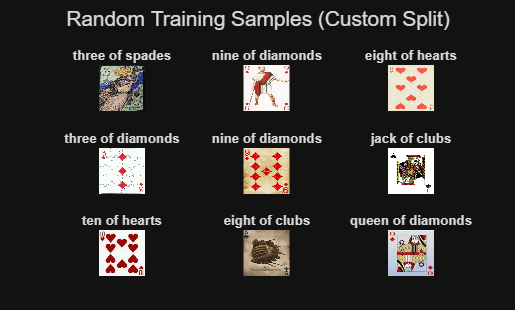


% ----

% Random visualization
numSamples = 9;

randIdx = randperm(numel(imdsTrain.Files), numSamples);

figure;
for i = 1:numSamples
    img = readimage(imdsTrain, randIdx(i));

    subplot(3,3,i);
    imshow(img);

    title(string(imdsTrain.Labels(randIdx(i))), ...
        'Interpreter', 'none', ...
        'FontSize', 8);
end

sgtitle('Random Training Samples (Custom Split)');

### Part B - Build and Visualize the Data Matrix T

This part will reshape the pixel matrices from the images into a large input matrix T, containing all the training data. The process can be described by the following steps:

- Slice original image into columns vectors of pixels

- Vertically concatenate each column with the next

- Repeat 1 & 2 for each training image

- Horizontally concatenate the reshaped image vectors (9216,1) into a (9216,N_samples) matrix.

% Define image size
imgSize = [96 96];

numImages = numel(imdsTrain.Files);
numPixels = prod(imgSize);

% Preallocate data matrix
T = zeros(numPixels, numImages);

% Build matrix T
for i = 1:numImages
    
    img = readimage(imdsTrain, i);
    
    % Convert to grayscale
    if size(img,3) == 3
        img = rgb2gray(img);
    end
    
    % Resize to consistent dimensions
    img = imresize(img, imgSize);
    
    % Convert to double for PCA
    img = im2double(img);
    
    % Flatten (column-wise stacking)
    vec = img(:);
    
    % Store as column
    T(:, i) = vec;
end

disp("Data matrix size:");

Data matrix size:


disp(size(T));   % [50176, N]

        9216        5710



**Visualize the Data Matrix T**

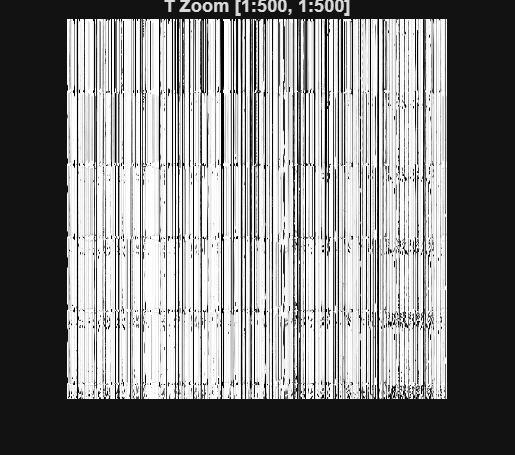

% Define region of interest
rowStart = 1;
rowEnd   = 500;

colStart = 1;
colEnd   = 500;

T_zoom = T(rowStart:rowEnd, colStart:colEnd);

figure;
imshow(T_zoom, []);
title(sprintf('T Zoom [%d:%d, %d:%d]', rowStart, rowEnd, colStart, colEnd));

**Analysis:** There isn't much going on in here. Most pixels are white, which makes sense given the common visual structure of playing cards. There are black streaks that represent the graphics on the cards, including the suit symbol, value, and artwork on the card.

### Part C - Mean Face

This section will compute the mean face of the card images

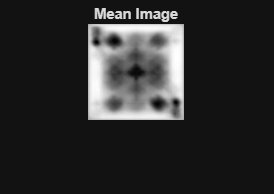

% Compute the mean across the rows 
m = mean(T, 2);

meanImg = reshape(m, imgSize);

figure;
imshow(meanImg, []);
title('Mean Image');

The mean image looks similar to a real playing card, with a color emphasis in regions of shared attributes across the various cards. This includes the card identifier in the top left and bottom right, as well as the arrangement of the suit symbols across the center area of the card.

### Part D - PCA Analysis

This section will implement PCA from scratch to avoid the pca() functions overhead. Unfortunately, passing the raw pixel intensities presented memory errors in the system, prompting this approach instead.

% Center the data with the mean
A = T - m;

% Calculate the reduced covariance matrix
C = A' * A;

% Compute the eigenvalues
[U, S] = eig(C);

% Sort eigenvalues descending
[eigenvals, idx] = sort(diag(S), 'descend');
U = U(:, idx);

% Calculate the explained variance
explained = eigenvals / sum(eigenvals) * 100;
cumVar = cumsum(explained);

k = find(cumVar >= 95, 1);

fprintf('Components for 95%% variance: %d\n', k);

Components for 95% variance: 710


The following code block will plot the percent variance explained vs. the eigenvectors. It will also highlight the calculated point for 95% variance, which we will use moving forward for our model.

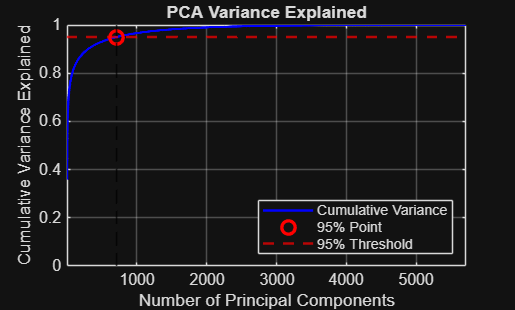

% Convert to 0–1 scale
cumVarNorm = cumVar / 100;

% X-axis: component index
x = 1:length(cumVarNorm);

figure;
plot(x, cumVarNorm, 'b', 'LineWidth', 1.5);
hold on;

% Highlight 95% point
plot(k, cumVarNorm(k), 'ro', 'MarkerSize', 8, 'LineWidth', 2);

% Horizontal dotted line at 95%
yline(0.95, 'r--', 'LineWidth', 1.5);

% Vertical line at k
xline(k, 'k--', 'LineWidth', 1);

% Labels
xlabel('Number of Principal Components');
ylabel('Cumulative Variance Explained');
title('PCA Variance Explained');

% Axis limits
ylim([0 1]);
xlim([1 length(cumVarNorm)]);

grid on;
legend('Cumulative Variance', '95% Point', '95% Threshold', 'Location', 'southeast');

**Analysis:** The plot shows that the percent variance described by the eigenvectors increases exponentially for the first 1000 or so eigenvectors, before saturating near 2000 eigenvectors. 95% seems to be on the latter end of the exponential decay, so for computational effort, it may have been better to use a 90% variance threshold. Regardless, for 95% variance, 710 principal components will be used.

The following block of code will plot the top 9 eigenvectors as reshaped images to visualize the features of the data they represent.

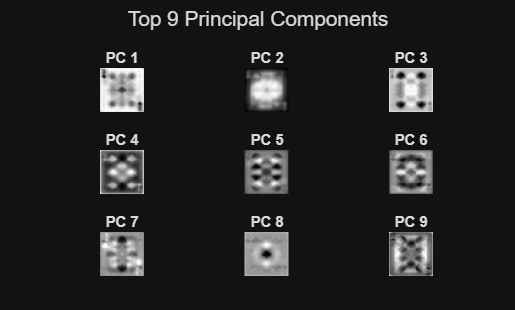

% Compute the pixel space eigenvectors
V = A * U;   % size: 50176 x 7624

% Normalize eigenvectors
for i = 1:size(V,2)
    V(:,i) = V(:,i) / norm(V(:,i));
end

% Extract the top 9 eigenvectors
V_top = V(:, 1:9);

% Reshape and display these eigenvectors
figure;

for i = 1:9
    eigImg = reshape(V_top(:,i), imgSize);
    
    subplot(3,3,i);
    imshow(eigImg, []);
    title(sprintf('PC %d', i));
end

sgtitle('Top 9 Principal Components');

**Analysis:** These top principal components show the dominant patterns of variation across the dataset, not actual cards. The first few eigenvectors capture large-scale, consistent structure, most notably the card outline (bright/dark borders) and global symmetry, which is expected since all cards share the same rectangular shape and centered layout. You can also see recurring emphasis in the corner regions, where rank and suit symbols typically appear, indicating that these areas contribute strongly to variance. Later components begin to highlight more localized patterns, such as clusters resembling suit positions or central symbols, though they appear blurred because PCA averages variation rather than isolating discrete features. Overall, these eigenvectors tell us that the dataset's variance is dominated by 

## Part 2 - Feature Extraction

This part will project the training and testing images into the K-dimensional eigenvector space to obtain compact feature vectors.

### Part A - Project Training Images

numTrain = numel(imdsTrain.Files);
V_k = V(:, 1:k);
K = size(V_k, 2);

% Initialize feature + label matrices
W_train = zeros(K, numTrain);
y_train = zeros(numTrain, 1);

for i = 1:numTrain
    
    % Read image
    img = readimage(imdsTrain, i);
    
    % Grayscale
    if size(img,3) == 3
        img = rgb2gray(img);
    end
    
    % Resize
    img = imresize(img, imgSize);
    
    % Convert
    img = im2double(img);
    
    % Vectorize
    vec = img(:);
    
    % Center using training mean
    vec_centered = vec - m;
    
    % Project into PCA space
    w = V_k' * vec_centered;
    
    % Store feature vector
    W_train(:, i) = w;
    
    % Extract label (from folder name)
    y_train(i) = double(imdsTrain.Labels(i));
end

% Display sizes
fprintf('W_train size: %d x %d\n', size(W_train,1), size(W_train,2));

W_train size: 710 x 5710


fprintf('y_train size: %d x %d\n', size(y_train,1), size(y_train,2));

y_train size: 5710 x 1


### Part B - Project Testing Images

numTest = numel(imdsTest.Files);
K = size(V_k, 2);

% Initialize feature + label matrices
W_test = zeros(K, numTest);
y_test = zeros(numTest, 1);

for i = 1:numTest
    
    % Read image
    img = readimage(imdsTest, i);
    
    % Grayscale
    if size(img,3) == 3
        img = rgb2gray(img);
    end
    
    % Resize
    img = imresize(img, imgSize);
    
    % Convert
    img = im2double(img);
    
    % Vectorize
    vec = img(:);
    
    % Center using training mean
    vec_centered = vec - m;
    
    % Project into PCA space
    w = V_k' * vec_centered;
    
    % Store feature vector
    W_test(:, i) = w;
    
    % Extract label
    y_test(i) = double(imdsTest.Labels(i));
end

% Display sizes
fprintf('W_test size: %d x %d\n', size(W_test,1), size(W_test,2));

W_test size: 710 x 1208


fprintf('y_test size: %d x %d\n', size(y_test,1), size(y_test,2));

y_test size: 1208 x 1


## Part 3 - Card Recognition

This section will train and evaluate classifiers using the previously computed PCA features

### Part A - KNN Classifier

This section will train a KNN classifier on W_train and y_train.

% Ensure correct orientation: samples x features
X_train = W_train';
X_test  = W_test';

% K values to test
K_values = [1, 3, 5, 7];

accuracies = zeros(length(K_values), 1);

for i = 1:length(K_values)
    
    K = K_values(i);
    
    % Train KNN model
    mdl = fitcknn(X_train, y_train, ...
        'NumNeighbors', K, ...
        'Standardize', true);
    
    % Predict on test data
    y_pred = predict(mdl, X_test);
    
    % Compute accuracy
    acc = sum(y_pred == y_test) / length(y_test) * 100;
    
    accuracies(i) = acc;
end

%% Display results in table

resultsTable = table(K_values', accuracies, ...
    'VariableNames', {'K', 'Accuracy_percent'});

disp(resultsTable);

    K    Accuracy_percent
    _    ________________

    1         20.695     
    3         14.983     
    5         13.162     
    7         12.169     



**Analysis:** Peak observed accuracy is 20.695%. This is very low, but not unexpected for this dataset. With 53 classes, random guessing would yield an accuracy 1.9%. Our result for the KNN classifier shows a 10x performance increase compared to the random guessing case. Regardless though, the generally low accuracy indicates that the PCA isn't able to translate the raw pixel intensities into discriminative features for analysis. PCA captures directions of maximum variance, which may not correlate to areas tied to class separation. For example, what actually varies in the images are lighting, background shading, and rotations. Meanwhile, what really matters for classification are things like the suit symbols, rank text, and corner details. Therefore, additional preprocessing must be done to convert the raw pixel intensities into a more meaningful feature before applying PCA. The next step is to try using edge detection methods on the raw images before PCA and observing the difference in performance. I will also run both setups on additional SVM models.

### Part B - SVM Classifiers

This section will train an SVM classifier on W_train and y_train. The Classifiers will be a combination of one-vs-one and one-vs-all classifiers with various kernels, including linear, 3rd order polynmomial, and Gaussian RBF.

%% Assume X_train, X_test, y_train, y_test already exist

y_train = y_train(:);
y_test  = y_test(:);

% Kernel Definitions
kernels = { ...
    'Linear', 'Linear', struct('KernelFunction','linear','BoxConstraint',1.0)
};

% Strategies
strategies = { ...
    'OvA', 'onevsall'
};

% Storage
training_times = struct();
accuracies = struct();

% Loop through the kernels
for k = 1:size(kernels,1)

    display_name = kernels{k,1};
    kernel_key   = kernels{k,2};
    params       = kernels{k,3};

    for s = 1:size(strategies,1)

        strat_name = strategies{s,1};
        coding_type = strategies{s,2};

        % Define template SVM
        t = templateSVM( ...
            'KernelFunction', params.KernelFunction, ...
            'BoxConstraint', params.BoxConstraint ...
        );

        % Train ONCE with template and chosen strategy
        tic;
        model = fitcecoc(X_train, y_train, ...
            'Learners', t, ...
            'Coding', coding_type);
        train_time = toc;

        % Prediction
        y_pred = predict(model, X_test);
        acc = mean(y_pred == y_test) * 100;

        training_times.(kernel_key).(strat_name) = train_time;
        accuracies.(kernel_key).(strat_name) = acc;
    end
end

% Display Results
fprintf('\nTraining Time (seconds)\n');


Training Time (seconds)


fprintf('-------------------------------\n');

-------------------------------


fprintf('%-22s%10s\n','Kernel','OvA');

Kernel                       OvA



for k = 1:size(kernels,1)
    display_name = kernels{k,1};
    kernel_key   = kernels{k,2};

    fprintf('%-22s%10.3f\n', display_name, ...
        training_times.(kernel_key).OvA);
end

Linear                   375.954



fprintf('\nTest Accuracy (%%)\n');


Test Accuracy (%)


fprintf('-------------------------------\n');

-------------------------------


fprintf('%-22s%10s\n','Kernel','OvA');

Kernel                       OvA



for k = 1:size(kernels,1)
    display_name = kernels{k,1};
    kernel_key   = kernels{k,2};

    fprintf('%-22s%10.2f\n', display_name, ...
        accuracies.(kernel_key).OvA);
end

Linear                     29.39


**Analysis:** The KNN classifier achieved a peak accuracy of 20.695% at K=1, with performance decreasing as K increased. While this is well above the 1.9% random guessing baseline for 53 classes, it remains low in absolute terms. This is expected because KNN relies on distance in feature space, and PCA features derived from raw pixel intensities are dominated by  variations like lighting, card orientation, and card font/artwork rather than the discriminative details that actually distinguish cards, such as the small rank text and suit symbols in the corners. Two visually different cards, say a three of hearts and a king of spades, can have very similar overall pixel distributions if they share the same artwork and font, causing KNN to confuse them. Meanwhile, two images of the same card under different lighting can appear far apart in feature space.

The linear SVM achieved an accuracy of 29.39% using a one-vs-all strategy. This outperformed KNN, which is consistent with the fact that SVM finds optimal separating hyperplanes rather than relying on raw distance. However, accuracy remains low because the underlying PCA features still encode pixel intensity patterns that are only weakly correlated with card identity. Playing cards seem like they should be easy to classify because humans immediately focus on the rank and suit symbols, which occupy a small fraction of the total image area. PCA, however, treats every pixel equally and captures directions of maximum variance across the entire image. This means the features are dominated by large-scale structure such as the card border, center artwork, and brightness gradients, while the small but critical corner symbols that actually define the card's class contribute minimally to the principal components. A more targeted feature extraction approach, such as edge detection or region-specific analysis, would be needed to better capture these discriminative details.

## Part 4 - Edge-based Feature Extracation and Classification

This part will replicate the same process in part 3, but with using edge detection as a feature instead of raw pixel intensities.

% Rebuild data matrix using Canny edge detection instead of raw pixels

% 4A - Build Edge Data Matrix
numTrain_edge = numel(imdsTrain.Files);
T_edge = zeros(numPixels, numTrain_edge);

for i = 1:numTrain_edge
    img = readimage(imdsTrain, i);
    if size(img, 3) > 1
        img = img(:,:,1);  % just take first channel regardless
    end
    img = imresize(img, imgSize);
    edgeImg = double(edge(img, 'canny'));
    T_edge(:, i) = edgeImg(:);
end

disp("Edge data matrix size:");

Edge data matrix size:


disp(size(T_edge));

        9216        5710




% 4B - PCA on Edge Features
m_edge = mean(T_edge, 2);
A_edge = T_edge - m_edge;

C_edge = A_edge' * A_edge;
[U_edge, S_edge] = eig(C_edge);

[eigenvals_edge, idx_edge] = sort(diag(S_edge), 'descend');
U_edge = U_edge(:, idx_edge);

explained_edge = eigenvals_edge / sum(eigenvals_edge) * 100;
cumVar_edge = cumsum(explained_edge);

k_edge = find(cumVar_edge >= 95, 1);
fprintf('Edge PCA - Components for 95%% variance: %d\n', k_edge);

Edge PCA - Components for 95% variance: 3266



% Compute pixel-space eigenvectors
V_edge = A_edge * U_edge;
for i = 1:size(V_edge, 2)
    V_edge(:, i) = V_edge(:, i) / norm(V_edge(:, i));
end

V_k_edge = V_edge(:, 1:k_edge);

% 4C - Project Training Images (Edge)
W_train_edge = zeros(k_edge, numTrain_edge);
y_train_edge = zeros(numTrain_edge, 1);

for i = 1:numTrain_edge
    img = readimage(imdsTrain, i);
    if size(img, 3) == 3
        img = rgb2gray(img);
    end
    img = imresize(img, imgSize);
    edgeImg = double(edge(img, 'canny'));
    vec = edgeImg(:);
    vec_centered = vec - m_edge;
    W_train_edge(:, i) = V_k_edge' * vec_centered;
    y_train_edge(i) = double(imdsTrain.Labels(i));
end

% 4D - Project Testing Images (Edge)
numTest_edge = numel(imdsTest.Files);
W_test_edge = zeros(k_edge, numTest_edge);
y_test_edge = zeros(numTest_edge, 1);

for i = 1:numTest_edge
    img = readimage(imdsTest, i);
    if size(img, 3) == 3
        img = rgb2gray(img);
    end
    img = imresize(img, imgSize);
    edgeImg = double(edge(img, 'canny'));
    vec = edgeImg(:);
    vec_centered = vec - m_edge;
    W_test_edge(:, i) = V_k_edge' * vec_centered;
    y_test_edge(i) = double(imdsTest.Labels(i));
end

% 4E - KNN on Edge Features
X_train_edge = W_train_edge';
X_test_edge  = W_test_edge';

K_values = [1, 3, 5, 7];
accuracies_knn_edge = zeros(length(K_values), 1);

for i = 1:length(K_values)
    K = K_values(i);
    mdl = fitcknn(X_train_edge, y_train_edge, ...
        'NumNeighbors', K, ...
        'Standardize', true);
    y_pred = predict(mdl, X_test_edge);
    accuracies_knn_edge(i) = sum(y_pred == y_test_edge) / length(y_test_edge) * 100;
end

resultsTable_edge = table(K_values', accuracies_knn_edge, ...
    'VariableNames', {'K', 'Accuracy_percent'});
disp('KNN Results (Edge Features):');

KNN Results (Edge Features):


disp(resultsTable_edge);

    K    Accuracy_percent
    _    ________________

    1         8.7748     
    3          5.298     
    5         4.1391     
    7         3.7252     




% 4F - SVM on Edge Features
y_train_edge = y_train_edge(:);
y_test_edge  = y_test_edge(:);

t = templateSVM('KernelFunction', 'linear', 'BoxConstraint', 1.0);

tic;
model_edge = fitcecoc(X_train_edge, y_train_edge, ...
    'Learners', t, ...
    'Coding', 'onevsall');
train_time_edge = toc;

y_pred_edge = predict(model_edge, X_test_edge);
acc_edge = mean(y_pred_edge == y_test_edge) * 100;

fprintf('\nSVM Results (Edge Features):\n');


SVM Results (Edge Features):


fprintf('Training Time: %.3f seconds\n', train_time_edge);

Training Time: 538.403 seconds


fprintf('Test Accuracy: %.2f%%\n', acc_edge);

Test Accuracy: 29.47%


**Analysis:** Using edge mapping caused the KNN performance to degrade substantially, with the accuracy dropping by ~20% for KNN with K = 1 (our best performance). The SVM improved marginally, with a neglible increase in accuracy. There are a few observations from the system output, including:

- **Why did edge features need more PCA components (3266 vs. 710 - **Because edge maps are binary and sparse, containing mostly zeros with ones scattered along edges, the variance is spread across many dimensions. Compare this to the raw pixel intensities, where there are large regions of similar brightness and thus fewer PCA components.

- **Why did SVM improve by KNN got worse - **SVM is a margin-based classifier by finding separating hyperplanes. Edge features, despite being higher dimensional, give the SVM cleaner decision boundaries because edges encode the actual discriminative structure (suit shapes, rank outlines) without the noise of lighting and shading variation. So SVM benefits in this case. KKNN, however, relies on distance between points. In 3266 dimensions, the large dimensionality causes all the distances to become nearly equal (less meaningful) and making KNN perform worse. With raw pixels, there were fewer PCA components, so the distance metric was more meaningful.

In general, edge detection helps SVM by removing irrelevant intensity variation, but hurts KNN by creating a high-dimensional sparse space where distance metrics break down.

## Part 5 - Template Matching

This section will investigate template matching for this dataset by the performing the following steps:

- Building & loading the template database

- Implementing the template matching algorithm

- Running a test and evaluating performance

### Part A - Load & Build Template Database

I manually created a folder called "template" that contains hand crafted images that I thought could best represent a template for each class. This section builds a function for loading the templates.

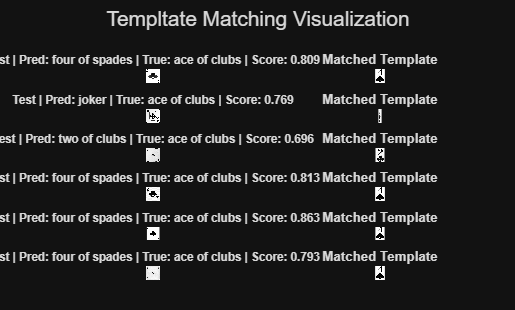

function templates = loadTemplates()

% Create directory to template folder
templateFolder = fullfile(pwd, 'input', 'template');

% Assemble a list of files from the folder
files = [ ...
    dir(fullfile(templateFolder, '*.jpg')); ...
    dir(fullfile(templateFolder, '*.png')) ...
];

% Error check
if isempty(files)
    error("No template images found. Check folder path or file extensions.");
end

numTemplates = length(files);

templates = struct('name', cell(numTemplates,1), ...
                   'img',  cell(numTemplates,1));

% Assemble struct of template card files
for i = 1:numTemplates
    
    name = erase(files(i).name, '.jpg');
    name = erase(name, '.png');
    
    img = imread(fullfile(templateFolder, files(i).name));
    
    % Convert to grayscale
    if size(img, 3) == 3
        img = rgb2gray(img);
    end
    
    img = im2double(img);
    
    templates(i).name = lower(string(name));
    templates(i).img  = img;
end

end

### Part B - Template Matching Algorithm

This section will implement a function for performing the template matching algorithm, which includes sliding the manually crafted template files across a small region in the corner of a test image. 

function [bestLabel, bestScore] = matchTemplate(testImg, templates)

% Convert to grayscale

Template Matching Accuracy: 18.96%


if size(testImg, 3) == 3
    testImg = rgb2gray(testImg);
end
testImg = im2double(testImg);

% Standardize test image size
testImg = imresize(testImg, [96 96]);

% Crop to upper-left region where rank/suit lives
searchRegion = testImg(1:45, 1:40);

% Template target heights to try (multi-scale)
targetHeights = [15, 20, 25, 30, 35];

bestScore = -inf;
bestLabel = "";

for i = 1:length(templates)
    
    tmpl = templates(i).img;
    [origH, origW] = size(tmpl);
    aspect = origW / origH;
    
    for t = 1:length(targetHeights)
        
        newH = targetHeights(t);
        newW = round(newH * aspect);
        
        scaledTmpl = imresize(tmpl, [newH newW]);
        
        [srH, srW] = size(searchRegion);
        
        % Skip if template is larger than search region
        if newH > srH || newW > srW
            continue;
        end
        
        % Normalized cross-correlation
        c = normxcorr2(scaledTmpl, searchRegion);
        
        peakScore = max(c(:));
        
        if peakScore > bestScore
            bestScore = peakScore;
            bestLabel = templates(i).name;
        end
    end
end

end

### Part C - Run on Dataset

This section will run the functions implemented in the previous parts to perform templtate matching, with an evaluation step.

% Load the templates
templates = loadTemplates();

% Initialize test parameters
numTest = numel(imdsTest.Files);

predLabels = strings(numTest, 1);
trueLabels = strings(numTest, 1);

numToPlot = 6;
plotCount = 1;

figure;

for i = 1:numTest
    
    img = readimage(imdsTest, i);
    
    [label, score] = matchTemplate(img, templates);
    
    predLabels(i) = label;
    trueLabels(i) = lower(string(imdsTest.Labels(i)));
    
    % --- Plot a few examples ---
    if plotCount <= numToPlot
        
        % Find the matched template
        matchIdx = find([templates.name] == label, 1);
        
        % Prepare test image for display
        dispImg = img;
        if size(dispImg, 3) == 3
            dispImg = rgb2gray(dispImg);
        end
        dispImg = im2double(dispImg);
        
        subplot(numToPlot, 2, 2*plotCount - 1)
        imshow(dispImg, [])
        title(sprintf('Test | Pred: %s | True: %s | Score: %.3f', label, trueLabels(i), score), 'FontSize', 7)
        
        subplot(numToPlot, 2, 2*plotCount)
        if ~isempty(matchIdx)
            imshow(templates(matchIdx).img, [])
        else
            imshow(zeros(30, 30))
        end
        title("Matched Template", 'FontSize', 8)
        
        sgtitle("Templtate Matching Visualization")
        
        plotCount = plotCount + 1;
    end
end

accuracy = mean(strcmp(predLabels, trueLabels)) * 100;

fprintf("Template Matching Accuracy: %.2f%%\n", accuracy);